# QIBC Analysis

YFP2: Cdt1 IF stain

FarRed1: EdU

## Load data

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\C183_Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

conditions = {
    'release 24',2,2:10,1:4;
    'release 18',3,2:10,1:4;
    'release 15',4,2:11,1:4; 
    'Cycling',5:6,2:11,1:4; 
    'no 2nd primary',2,11,1:4;
    'no 2nd primary no click',3,11,1:4;

};

S = loadData_C183(conditions, dataDir);


**Bleedthrough from first round**

p =    51.9468
    0.0130


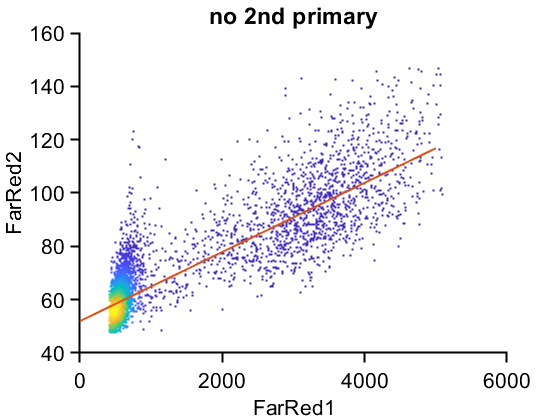

conds = [5];

xval = 'FarRed1';
%xbg = [xval 'bg'];
yval = 'FarRed2';
%ybg = [yval 'bg'];

gateVals = {};
rangeVals = {[2^6 2^14]}; 


for i = 1:length(conds)
    condition = conds(i);
    xdata = (S(condition).(xval));
    ydata =  (S(condition).(yval));
    
    totalGate = true(size(xdata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    xdata = xdata(totalGate);
    ydata = ydata(totalGate);
    %downsample = 5000;
    xmin = prctile(xdata,1); xmax = prctile(xdata,99.5);
    ymin = prctile(ydata,1); ymax = prctile(ydata,99.5);
    ind = xdata>xmin & xdata<xmax & ydata>ymin & ydata<ymax;
    %ind = randsample(length(xdata),downsample);
    xdata = xdata(ind); ydata = ydata(ind);
    figure, hold on
    dscatter(xdata,ydata);
    ylabel(yval);xlabel(xval);
    title(conditions{condition,1});
   % xlim([0 250]); ylim([0 600]);
   p =  robustfit(xdata,ydata)
    plot([0 5000],p(1)+p(2)*[0 5000])
end

**Set thresholds based on G1**

cond = 4;
figure
xval = 'YFP2';
yval = 'FarRed1';

xdata = log2(S(cond).(xval));
ydata = log2(S(cond).(yval));


inds = log2(S(cond).dna) < 20.9 & S(cond).cdk2 < .5;
xdata = xdata(inds);
ydata = ydata(inds);

% inds = xdata < prctile(xdata,95) & ydata < prctile(ydata,95);
% xdata = xdata(inds);
% ydata = ydata(inds);

EdUThresh = prctile(xdata,99)

EdUThresh = 7.4463

GMNNThresh = prctile(ydata,99)

GMNNThresh = 9.6744

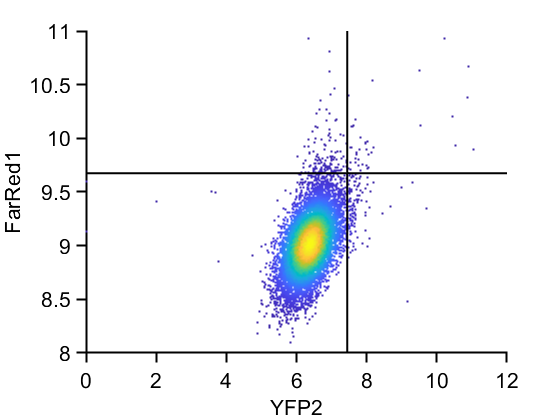


dscatter(xdata,ydata)
hline(GMNNThresh,'k');
vline(EdUThresh,'k');
ylabel(yval);xlabel(xval);

**Set thresholds based on S**

cond = 4;
figure
xval = 'FarRed2corr';
yval = 'YFP2';

xdata = (S(cond).(xval));
ydata = (S(cond).(yval));


inds = log2(S(cond).dna) > 21 &  log2(S(cond).dna) < 21.5 & S(cond).cdk2 > 1.2 ...
    & ydata > 1000 ;
xdata = xdata(inds);
ydata = ydata(inds);

% inds = xdata < prctile(xdata,99.5) & ydata < prctile(ydata,99.5);
% xdata = xdata(inds);
% ydata = ydata(inds);

cdt1Thresh = prctile(xdata,99)

cdt1Thresh = 95.8543

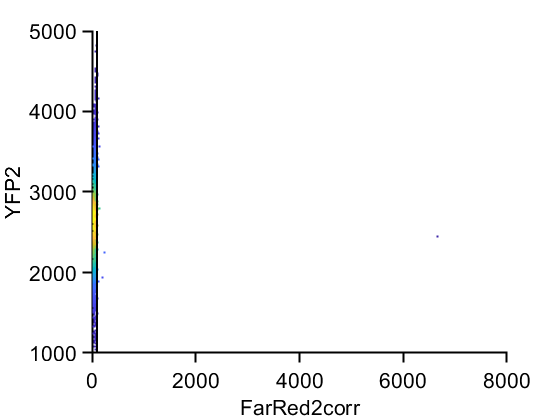


xdata = real(xdata);

dscatter(xdata,ydata)
vline(cdt1Thresh,'k');
ylabel(yval);xlabel(xval);

**Cdt1 vs EdU**

ans = 0.0074

ans =     2.4315   67.1328
   29.6978    0.7379


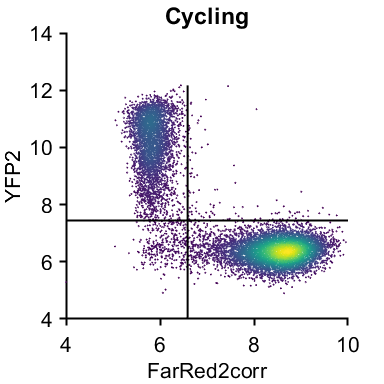

conds = [4];

xval = 'FarRed2corr';
%xbg = [xval 'bg'];
yval = 'YFP2';
%ybg = [yval 'bg'];

gateVals = {'dna','cdk2'};
rangeVals = {[2^20.4 2^21],[.7 1.2],[100 200]}; 


for i = 1:length(conds)
    condition = conds(i);
    xdata = log2(S(condition).(xval));
    ydata = log2(S(condition).(yval));
    
    totalGate = true(size(xdata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    xdata = xdata(totalGate);
    ydata = ydata(totalGate);
%     downsample = 4000;
%     xmin = prctile(xdata,1); xmax = prctile(xdata,99);
%     ymin = prctile(ydata,1); ymax = prctile(ydata,99);
%     ind = xdata>xmin & xdata<xmax & ydata>ymin & ydata<ymax;
%     ind = randsample(length(xdata),downsample);
%     xdata = xdata(ind); ydata = ydata(ind);
%     
    figure('units','inches','pos',[0 0 4 4]),
    colormap('viridis')
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o');
        hline(EdUThresh,'k')
    vline(log2(cdt1Thresh),'k')
    ylabel(yval);xlabel(xval);
    title(conditions{condition,1});
%     xlim([-50 700]); 
%     ylim([-50 3500]);
    sum(ydata > EdUThresh & xdata > log2(cdt1Thresh))/length(xdata)
    crosstab(ydata > EdUThresh,xdata > log2(cdt1Thresh))/length(xdata) * 100
    print_pdf([pwd() '\Figs\cdt1vsedu.pdf'])

end

**Cdt1 vs EdU**

ans = 0.3044

ans =    69.5643
   30.4357


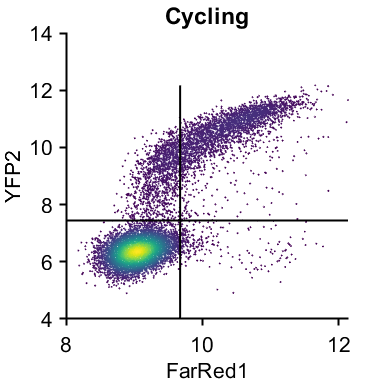

conds = [4];

xval = 'FarRed1';
%xbg = [xval 'bg'];
yval = 'YFP2';
%ybg = [yval 'bg'];

gateVals = {'dna','cdk2'};
rangeVals = {[2^20.4 2^21],[.7 1.2],[100 200]}; 


for i = 1:length(conds)
    condition = conds(i);
    xdata = log2(S(condition).(xval));
    ydata = log2(S(condition).(yval));
    
    totalGate = true(size(xdata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    xdata = xdata(totalGate);
    ydata = ydata(totalGate);
%     downsample = 4000;
%     xmin = prctile(xdata,1); xmax = prctile(xdata,99);
%     ymin = prctile(ydata,1); ymax = prctile(ydata,99);
%     ind = xdata>xmin & xdata<xmax & ydata>ymin & ydata<ymax;
%     ind = randsample(length(xdata),downsample);
%     xdata = xdata(ind); ydata = ydata(ind);
%     
    figure('units','inches','pos',[0 0 4 4]),
    colormap('viridis')
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o');
        hline(EdUThresh,'k')
    vline((GMNNThresh),'k')
    ylabel(yval);xlabel(xval);
    title(conditions{condition,1});
%     xlim([-50 700]); 
%     ylim([-50 3500]);
    sum(ydata > EdUThresh & xdata > log2(cdt1Thresh))/length(xdata)
    crosstab(ydata > EdUThresh,xdata > log2(cdt1Thresh))/length(xdata) * 100
    print_pdf([pwd() '\Figs\gmnnvsedu.pdf'])

end